clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


% Adjusts the A matrix as described in Examination 1
for i=1:4
    param.model.A(3*i,3*i) = -1;
end

## Design Procedure 1

param = control.DesignProcedure1(param,0);

Evaluation of design procedure 1 
Q is positive definite


ans =     0.2880    0.2892    0.2892    0.2892    0.7270    0.7275    0.7275    0.7275    1.3453    1.3453    1.3453    1.3493


R is positive definite


ans =    27.1436   37.5516   43.0021  114.6580  115.4977  115.6633  118.6280  124.1419  242.7167  318.9311  367.7529  952.4013


Gamma is found to be:


ans = 85.5366

Eigenvalues of the decoupled systems are all negative 


ans =   -1.3254 + 3.7937i  -1.3254 - 3.7937i  -0.9222 + 0.0000i  -1.3274 + 3.8404i  -1.3274 - 3.8404i  -0.9221 + 0.0000i  -1.3254 + 3.7937i  -1.3254 - 3.7937i  -0.9222 + 0.0000i  -1.3254 + 3.7937i  -1.3254 - 3.7937i  -0.9222 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.7753 + 5.2359i  -0.7753 - 5.2359i  -0.4258 + 5.9406i  -0.4258 - 5.9406i  -0.3169 + 6.1623i  -0.3169 - 6.1623i  -0.2890 + 6.1948i  -0.2890 - 6.1948i  -0.9280 + 0.0000i  -0.9296 + 0.0000i  -0.9297 + 0.0000i  -0.9300 + 0.0000i


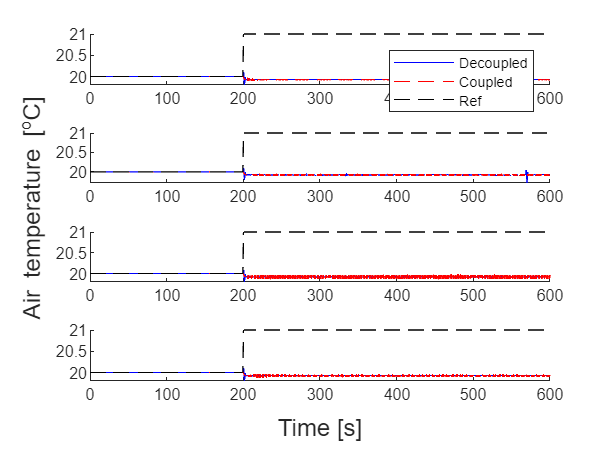

util.SimulateLinearStep(param,"Examination_Examination1_DP1",0);

## Design procedure 2

param = control.DesignProcedure2(param,0,1);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.1117    0.1126    0.1126    0.1127    0.4601    0.4602    0.4604    0.4607    2.4021    2.4084    2.4232    2.4356


Gamma is found to be:


ans = 1

Eigenvalues of the decoupled systems are all negative 


ans =    -4.1399   -0.0690   -1.0312   -4.1994   -0.0748   -1.0354   -4.1658   -0.0764   -1.0369   -4.1471   -0.0708   -1.0327


Eigenvalues of the coupled systems are all negative 


ans =    -4.2658   -4.3191   -4.3865   -4.4131   -0.0986   -0.1108   -0.1220   -0.1274   -1.0581   -1.0704   -1.0804   -1.0859


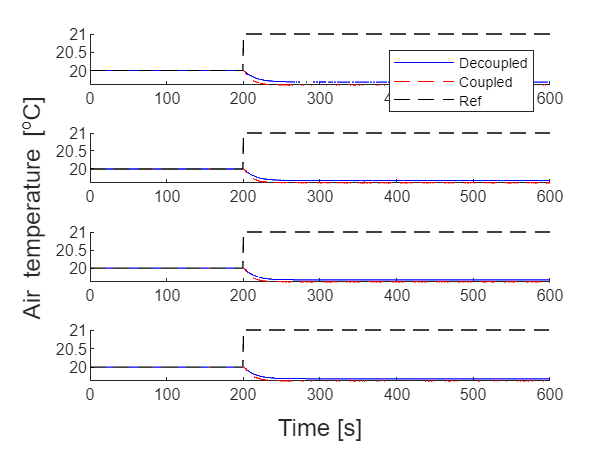

util.SimulateLinearStep(param,"Examination_Examination1_DP2",0);